# **ACM/IDS 104 - Problem Set 3 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## **Problem 3 (10 points) The K-Means Algorithm for Clustering**

In this problem, we will be implementing the K-Means Algorithm for clustering vectors in $\mathbb{R}^2$. To start, let us load and visualize our dataset.

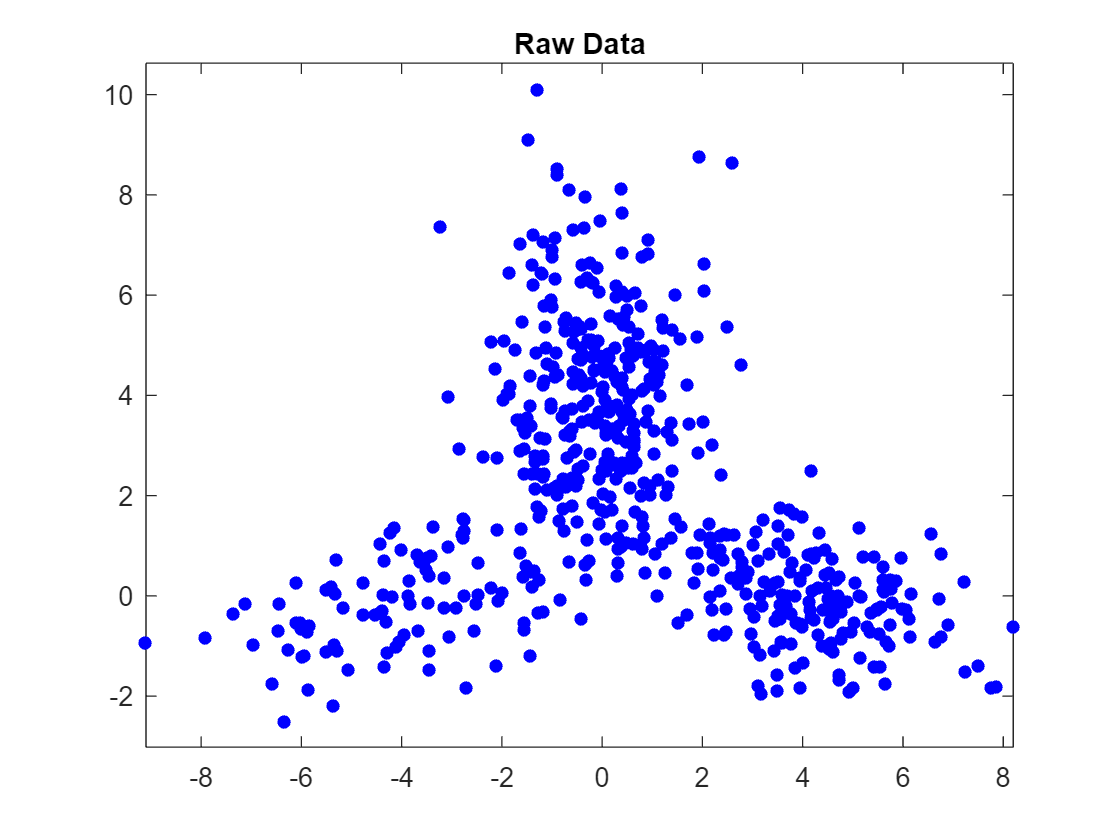

load clustering_data.mat
figure;
plot(x(:,1),x(:,2),'.b','MarkerSize',15);
title("Raw Data")
axis equal;
rng(2016); % for reproducibility

## **Part (a) The Algorithm**

In this part, we will implement the algorithm for $K=3$, which seems to be a reasonable number of clusters for this dataset. Show the clusters after the 1st, 5th, 10th and last iteration. This will illustrate the cluster evolution as the algorithm runs. $\texttt{subplot()}$ is very useful here.

To further aid our understanding of the algorithm, we will be keeping track of a few things:

- Keep track of the evolution of the representatives for each cluster. You can do so by updating the variable $\texttt{z}$ after each iteration.

- Keep track of the objective function value at each iteration.

Once you are done implementing the algorithm, feel free to change the value of $\texttt{K}$ and see how the clusterings are altered.

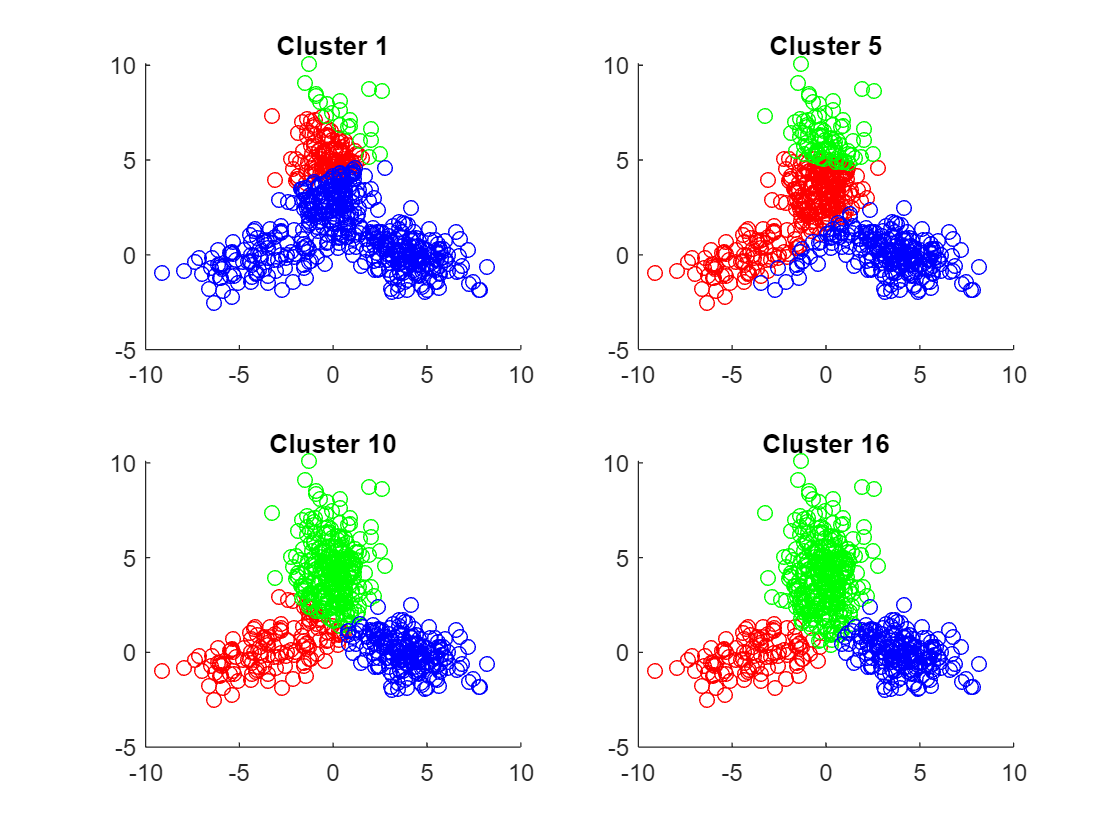

%{
Some useful setup done for you
%}
K = 3; % number of clusters
n = length(x); % number of vectors
c = zeros(n, 1); % clustering : c(i) is the cluster number for vector x(i, :)
iter = 0; % iteration number7
z = datasample(x, K); % initial representatives
%{
Step 1: Partitioning into clusters given our initial representatives
%}
for i = 1:n
    min_distance = Inf;
    min_cluster = -1;
    for k = 1:K
        dist = norm(x(i, :) - z(k, :));
        if dist < min_distance
            min_distance = dist;
            min_cluster = k;
        end
    end
    c(i) = min_cluster;
end


z_prev = 0;
plotting_indices = [1, 5, 10, 16];
plot_pos = 1;
colors = ['r', 'g', 'b'];
objective_functions = [];
cluster_representatives = [];
while z_prev ~= z
    z_prev = z(:, :);
    % Increment the iteration number and cluster reps
    iter = iter + 1;
    for k = 1:K
        subset_x = x(c == k, :);
        if ~isempty(subset_x)
            z(k, :) = mean(subset_x);
        end
    end
    cluster_representatives = [cluster_representatives, z];
    % Update cluster membership
    for i = 1:n
        min_distance = Inf;
        min_cluster = -1;
        for k = 1:K
            dist = norm(x(i, :) - z(k, :));
            if dist < min_distance
                min_distance = dist;
                min_cluster = k;
            end
        end
        c(i) = min_cluster;
    end
    % Recalculate objective function
    p_total = 0;
    for k = 1:K
        subset_x = x(c == k, :);
        for i = 1:length(subset_x)
            p_total = p_total + (norm(subset_x(i, :) - z(k, :))^2);
        end
    end
    p_total = p_total/n;
    objective_functions = [objective_functions, p_total];
    % Plotting
    if ismember(iter, plotting_indices)
        subplot(2, 2, plot_pos);
        color_index = 1;
        %cmap = jet(length(z));
        hold on;
        for k = 1:K
            subset_x = x(c == k, :);
            color = colors(color_index);
            scatter(subset_x(:, 1), subset_x(:, 2), 30, color);
            color_index = color_index + 1;
        end
        title(['Cluster ' num2str(iter)]);
        hold off;
        plot_pos = plot_pos + 1;
    end
end

## **Part (b) Evolution of Representatives**

Now, let us see the dynamics of the representatives. Plot the original (raw) data and the trajectories of the cluster representatives in one figure. $\texttt{squeeze()}$ might be useful here.

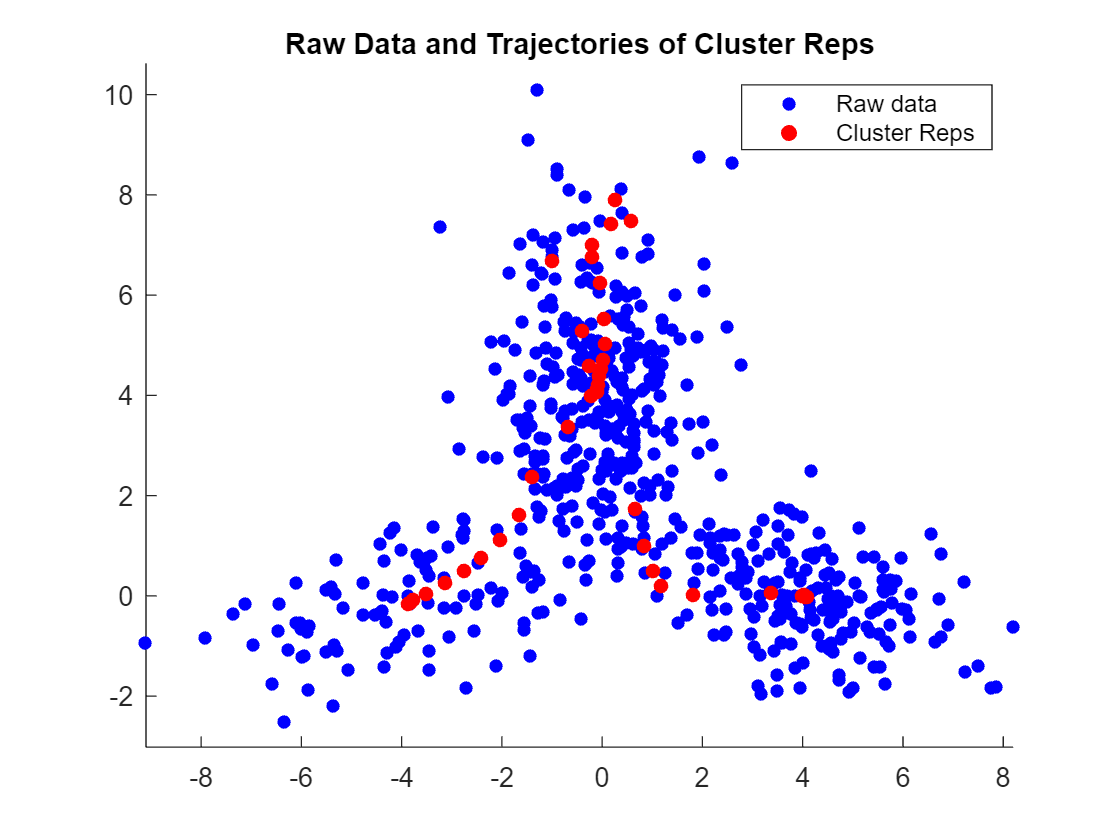

figure;
hold on;
% Raw Data
plot(x(:,1),x(:,2),'.b','MarkerSize', 15);
% Overlay plot with cluster reps in red
for i = 1:2:length(cluster_representatives)-1
    scatter(cluster_representatives(:, i), cluster_representatives(:, i + 1), 30, 'red', 'filled');
end
title("Raw Data and Trajectories of Cluster Reps")
axis equal;
legend('Raw data', 'Cluster Reps');
hold off;

## **Part (c) Objective Function**

Plot the values of the objective function against the iteration number. Does the trend match what we expect? Report the minimum value of the objective function using $\texttt{disp()}$.

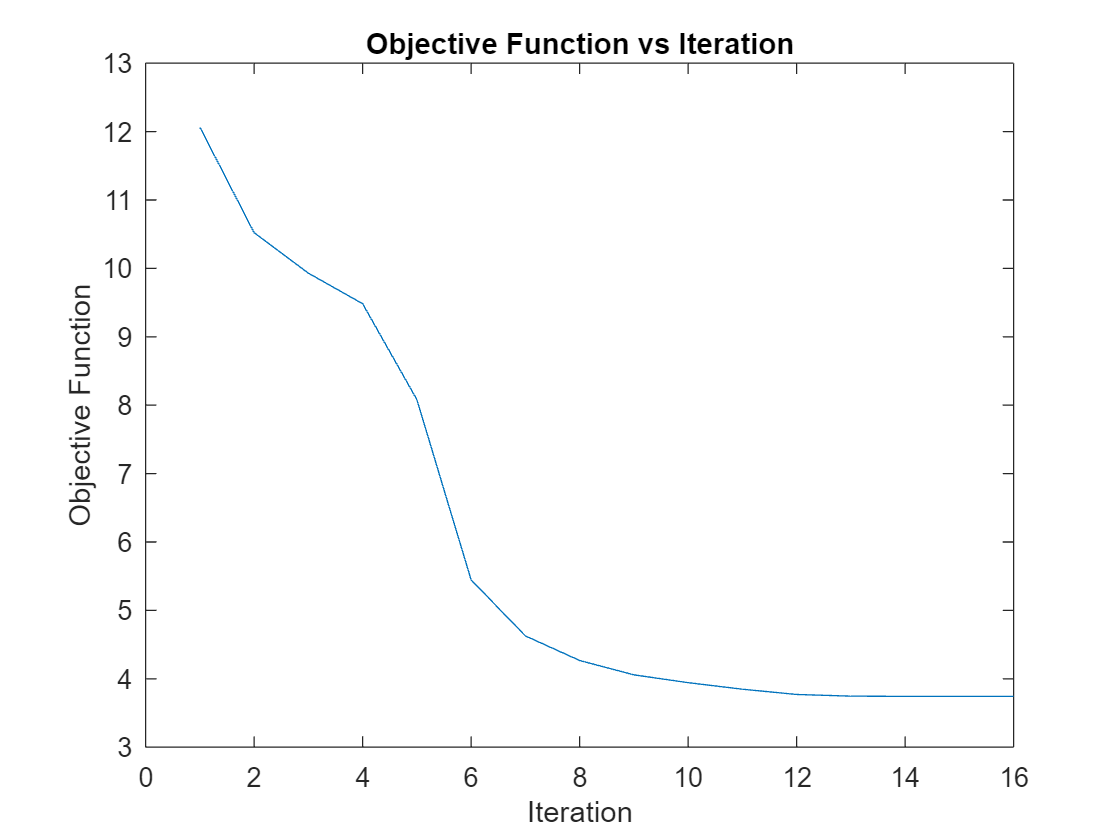

figure;
plot(1:iter, objective_functions);
title("Objective Function vs Iteration");
xlabel("Iteration");
ylabel("Objective Function");

% The trend matches what we expect because the objective function should be
% minimized each iteration.

% Display the minimum value
disp(['The minimum value of the objective function is: ', num2str(min(objective_functions))]);

The minimum value of the objective function is: 3.742


## **Part (d) Comparing with **$\texttt{kmeans()}$

The K-means algorithm is a very popular clustering algorithm and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, it exists as the built-in function $\texttt{kmeans()}$. In the simplest form, $\texttt{idx = kmeans(X, k)}$ performs K-means clustering to partition the rows in the data matrix $\texttt{X}$ into $\texttt{k}$ clusters, and returns a vector $\texttt{idx}$ containing cluster indices for each row. To compare your implementation with the built-in one, plot the clustering your obtained in (a) and the clustering obtained by using $\texttt{kmeans()}$.

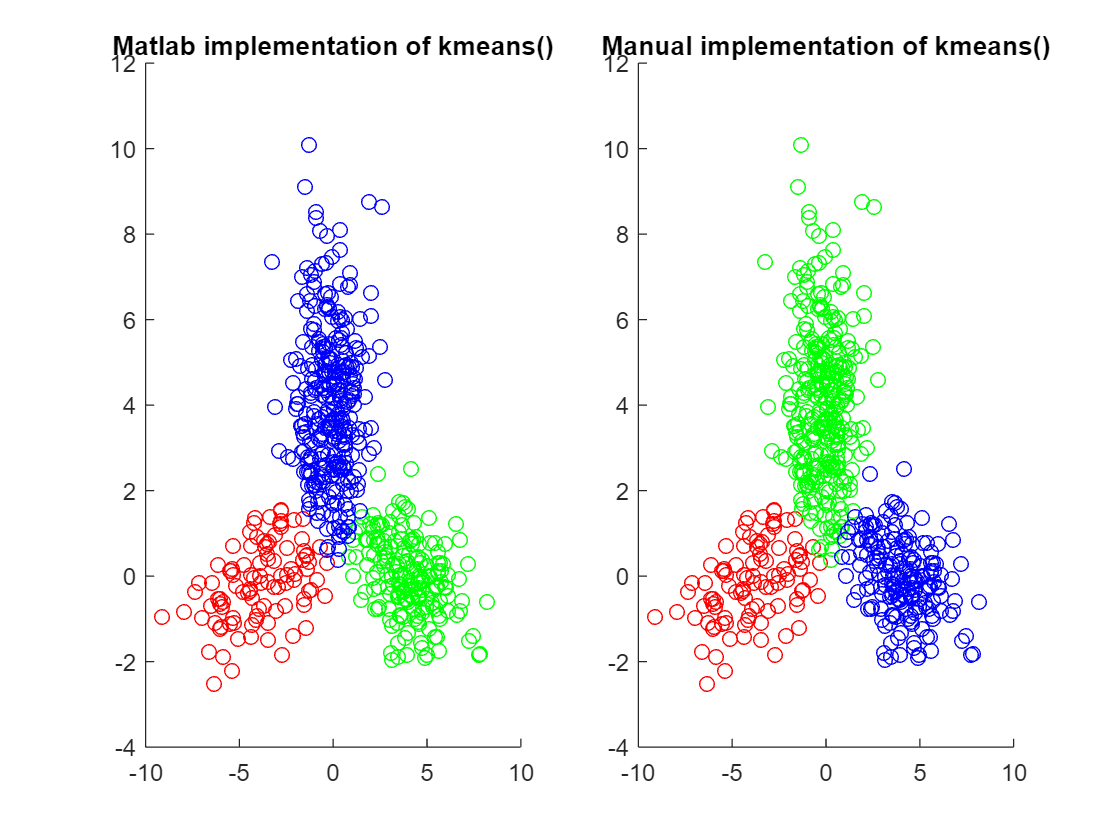

idx = kmeans(x, K);
figure;
subplot(1, 2, 1);
color_index = 1;
hold on;
for k = 1:K
    subset_x = x(idx == k, :);
    color = colors(color_index);
    scatter(subset_x(:, 1), subset_x(:, 2), 30, color);
    title('Matlab implementation of kmeans()')
    color_index = color_index + 1;
end
hold off;
subplot(1, 2, 2);
color_index = 1;
hold on;
for k = 1:K
    subset_x = x(c == k, :);
    color = colors(color_index);
    scatter(subset_x(:, 1), subset_x(:, 2), 30, color);
    title('Manual implementation of kmeans()')
    color_index = color_index + 1;
end
hold off;

## **Problem 5 (10 points) Gram Matrices for Text Classification**

Gram matrices are used in many different applications. Here is a simple example of application to classification of text documents. Suppose we have a collection of $n$ text documents and we want to measure similarity between them. First, we predefine a list of words (the "dictionary'') $w_1,w_2,w_3,\cdots , w_m$ appearing in the documents. Then, for each text $i$ we construct a vector $x_i\in\mathbb{R}^m$ whose $j^{\text{th}}$ component is the number of times the word $w_j$ appears in the text. This way, each text is represented as a vector in $\mathbb{R}^m$. This representation is often referred to as the "bag of words" representation. 

Let $\langle\cdot,\cdot\rangle$ be the usual dot product in $\mathbb{R}^m$ and $\|\cdot\|$ be the Euclidean norm. Let us normalize all vectors $z_i = \frac{x_i}{\|x_i\|}$ and define:


$$Z = [z_1\cdots z_n]\in\mathbb{M}_{m\times n}$$


Let $G$ be the Gram matrix associated with $z_1\cdots z_n$:


$$G = Z^TZ\in \mathbb{M}_{n\times n}$$


Since all $z_i$ are unit vectors:


$$G_{ij}=z_i^Tz_j=\|z_i\|\|z_j\|\cos\theta_{ij}=\cos\theta_{ij}$$


where $\theta_{ij}$is the angle between $z_i$ and $z_j$, which of course is the same as the angle between $x_i$ and $x_j$. This is widely use as a *measure of similarity* between documents. Hence, the more similar two texts $i$ and $j$ are, the closer $G_{ij}$ is to 1.

Now, let us apply this method to real texts. The task is to compare the text of the US Constitution ([found here](https://www.constituteproject.org/constitution/United_States_of_America_1992)) with the Wikipedia pages of Bernie Sanders, Hillary Clinton, Donald Trump, Ted Cruz, and John Kasich, and to find the page which is "closest" to the Constitution.

## Part (a) Setup

To start, we will define a list of $m=10$ words. To find the most "relevant words", copy the text of the Constitution and paste it into a word-cloud generator ([such as this one](http://worditout.com/word-cloud/make-a-new-one)). High frequency words appear large and we can form the dictionary from these words. Note that common sense is needed: words like "amendment'' and "section'' would appear large, but it makes no sense to include them into the dictionary. Also, it makes sense to include "United States'' as a single "word'', not two separate words, etc. But you are free to chose your own dictionary. In the code box below, please fill out the dictionary with your chosen words.

%{
DICTIONARY:
1) United States
2) Representative
3) President
4) Congress
5) Law
6) Office
7) Senate
8) Elector
9) Citizen
10) Power
%}

## Part (b) Fun

With your specified dictionary, let us see which Wikipedia page is closest. First, construct $n=6$ vectors (as specified above), one for each Wikipedia page and one for the Constitution. No need to get fancy here; just go to the related page and search for the number of occureneces of the words in your dictionary. Put all your results in a column vector for each candidate:

%{
Report your results here
%}
constitution = [88; 37; 121; 62; 60; 57; 29; 18; 22; 37];
sanders = [58; 30; 98; 61; 28; 29; 108; 11; 12; 14];
clinton = [50; 6; 134; 25; 46; 27; 61; 12; 7; 28];
trump = [75; 7; 186; 40; 66; 50; 21; 18; 6; 22];
cruz = [76; 6; 103; 35; 85; 21; 81; 13; 37; 12];
kasich = [17; 27; 71; 27; 37; 23; 19; 10; 7; 9];

%{
Normalize your vectors
%}
constitution = constitution / norm(constitution);
sanders = sanders / norm(sanders);
clinton = clinton / norm(clinton);
trump = trump / norm(trump);
cruz = cruz / norm(cruz);
kasich = kasich / norm(kasich);

%{
Construct the Gram matrix G as discussed
%}
Z = [constitution, sanders, clinton, trump, cruz, kasich];
G = Z' * Z


G =     1.0000    0.8551    0.9113    0.9364    0.8935    0.9392
    0.8551    1.0000    0.9010    0.7924    0.9038    0.8490
    0.9113    0.9010    1.0000    0.9577    0.9249    0.9263
    0.9364    0.7924    0.9577    1.0000    0.8637    0.9360
    0.8935    0.9038    0.9249    0.8637    1.0000    0.8715
    0.9392    0.8490    0.9263    0.9360    0.8715    1.0000


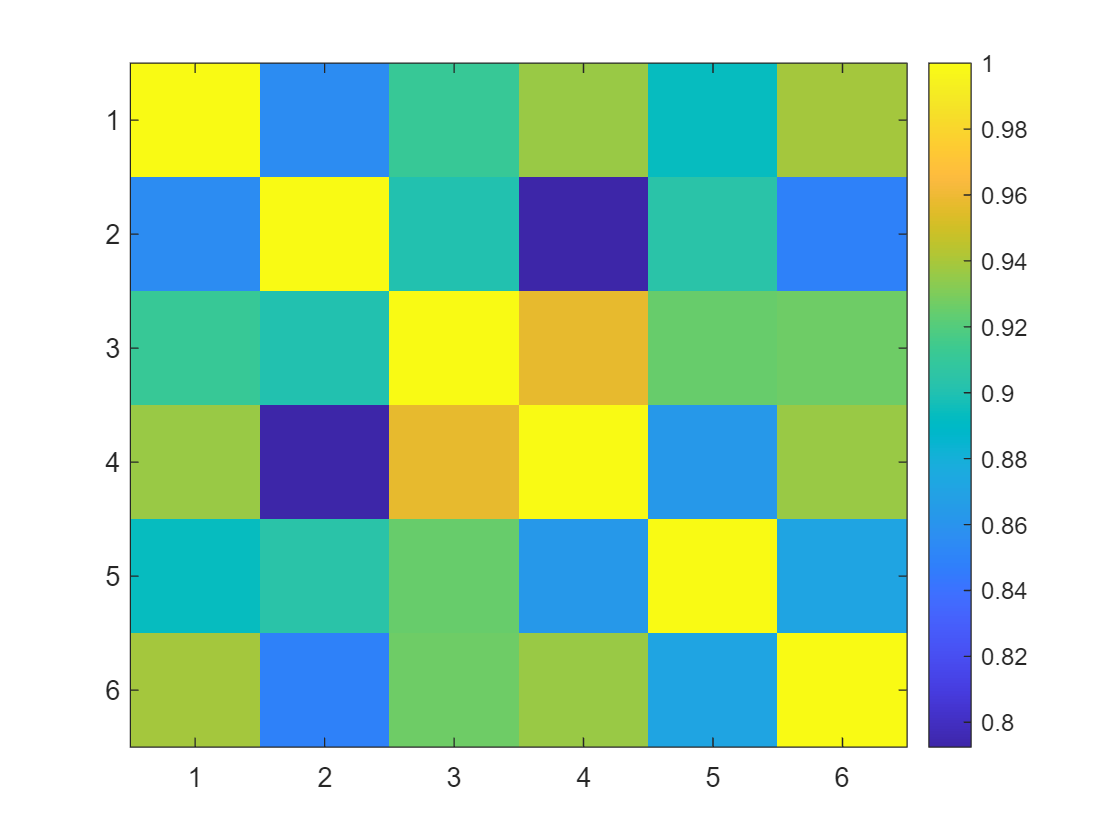

%{
You can visualize G by uncommenting the following lines of code
%}
figure;
imagesc(G);
colorbar;



%{
Find the page closest to the Constitution text and report your
answer using disp()
%}
kasich
%score

kasich =     0.1765
    0.2803
    0.7371
    0.2803
    0.3841
    0.2388
    0.1973
    0.1038
    0.0727
    0.0934


disp(G(1, 6));

    0.9392



Submit the obtained result to the corresponding piazza poll. Remember: this is not about your political preferences, it is about your data analysis :)